# Spring-mass-damper resonance

Use the slider controls to change the system mass, spring stiffness, and damping while noting how the natural period/frequency, impulse response, and transfer function change.

- How can you shift the natural frequency lower and higher?

- How can you broaden or sharpen the resonance?


clc
clear
close all

m = 100;
k = 24000;
b = 900;

wn = sqrt(k/m);
fn = wn/(2*pi);
Tn = 1/fn;
fprintf('Natural freq. [Hz]: %g',fn)

Natural freq. [Hz]: 2.46562

fprintf('Natural Period [s]: %g',Tn)

Natural Period [s]: 0.405578


G = tf([1],[m b k])

G =
 
             1
  -----------------------
  100 s^2 + 900 s + 24000
 
Continuous-time transfer function.



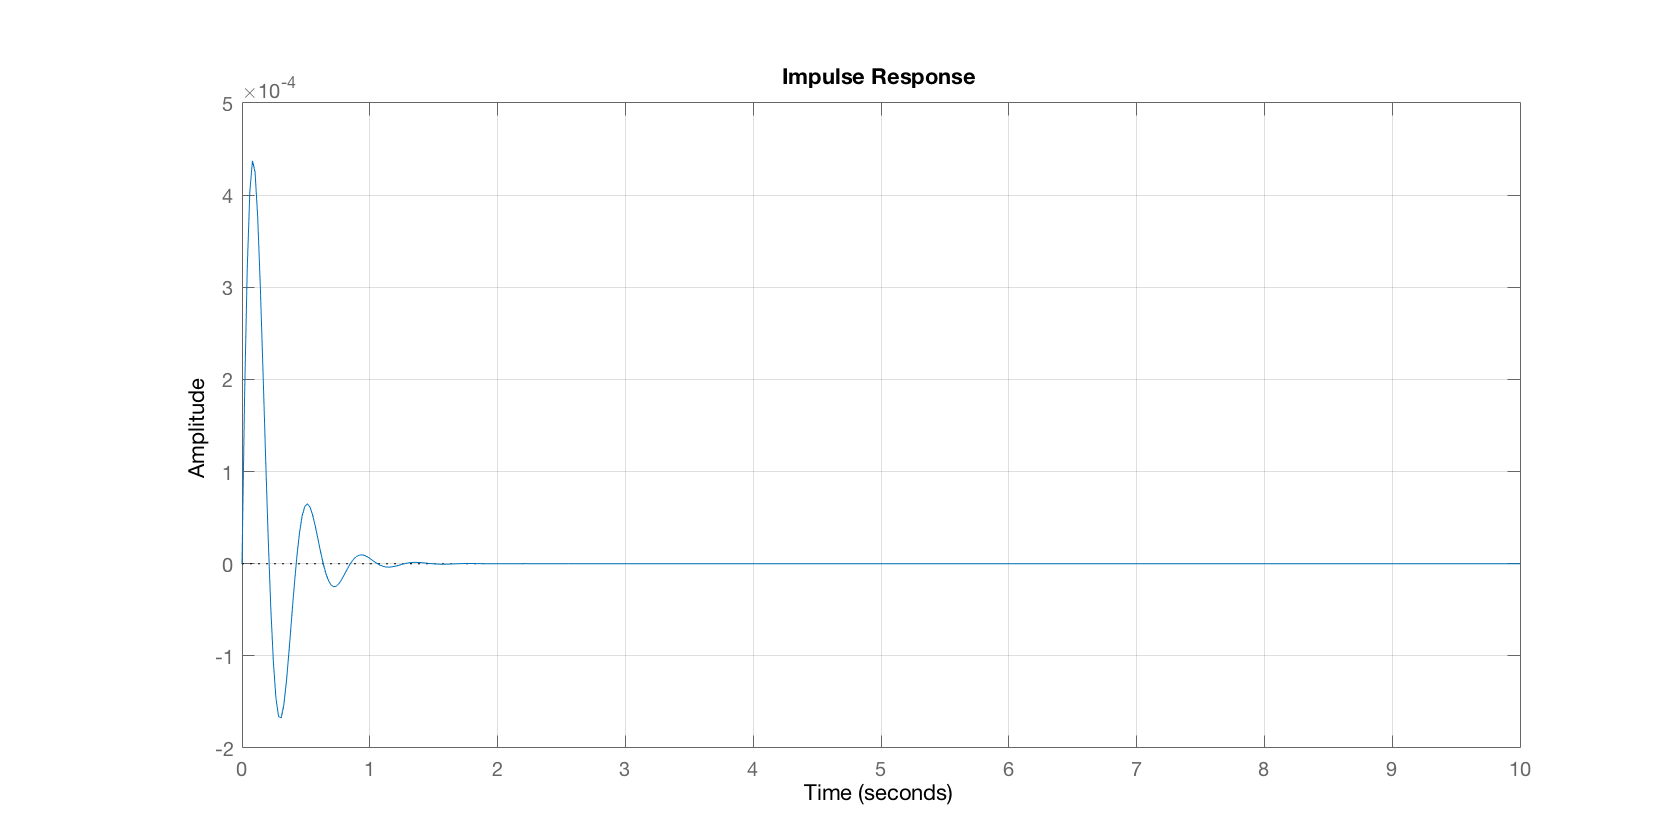

f(1) = figure();
f(1).Position = f(1).Position .* [1 1 1.5 1];
impulse(G,10)
grid on

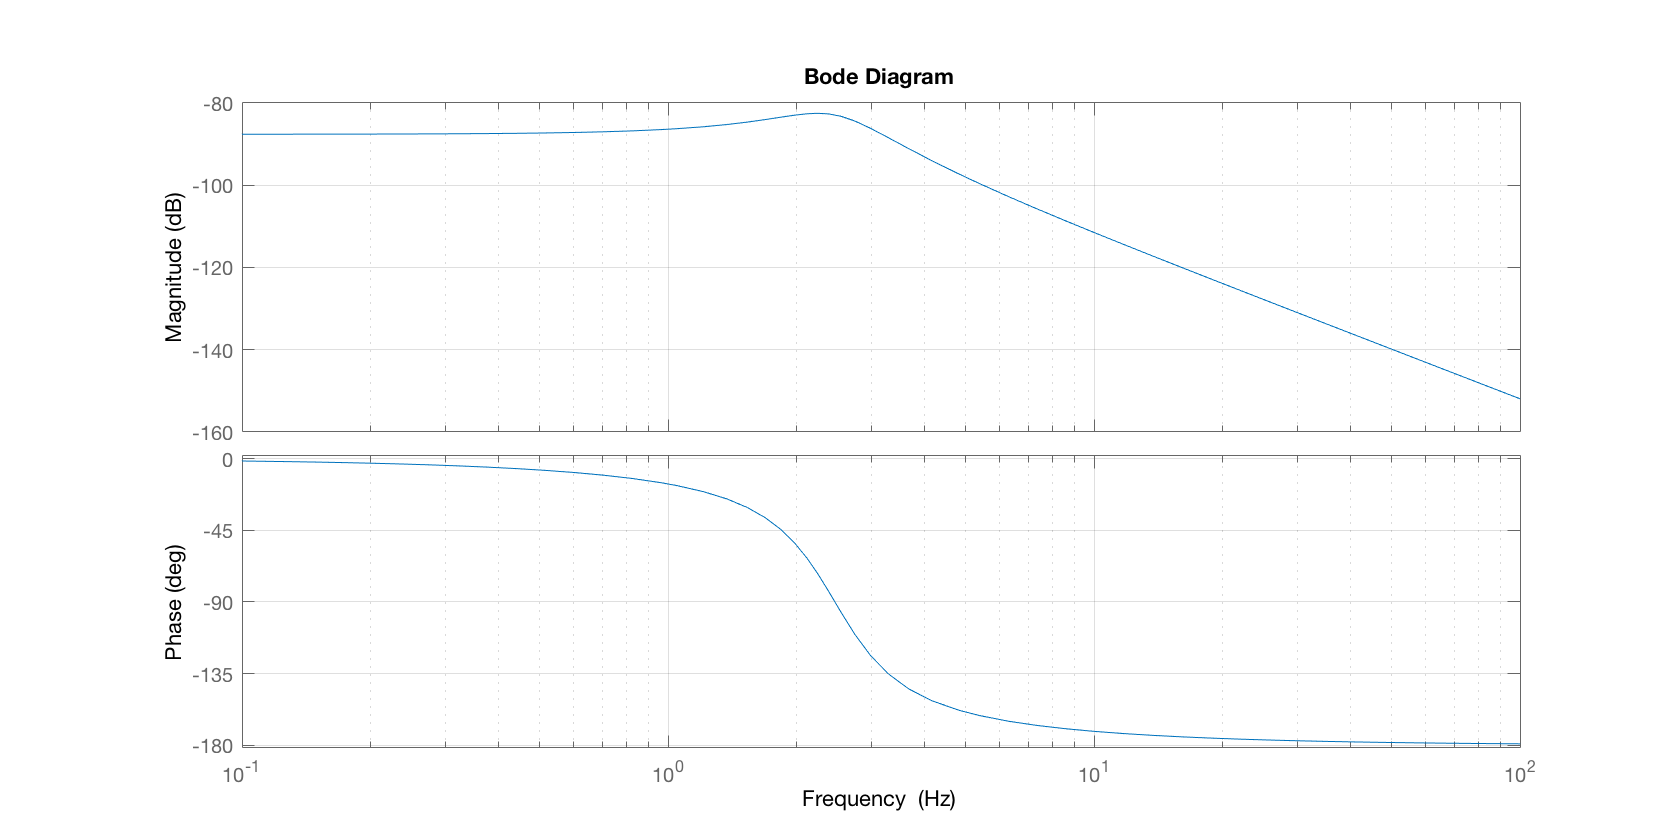


f(2) = figure();
f(2).Position = f(2).Position .* [1 1 1.5 1];
h = bodeplot(G);
setoptions(h,'FreqUnits','Hz','Grid','on')

% Copyright 2020 National Technology & Engineering Solutions of Sandia,
% LLC (NTESS). Under the terms of Contract DE-NA0003525 with NTESS, the
% U.S. Government retains certain rights in this software.
%
% This file is part of fbWecCntrl.
%
%     fbWecCntrl is free software: you can redistribute it and/or
%     modify it under the terms of the GNU General Public License as
%     published by the Free Software Foundation, either version 3 of
%     the License, or (at your option) any later version.
%
%     fbWecCntrl is distributed in the hope that it will be useful, but
%     WITHOUT ANY WARRANTY; without even the implied warranty of
%     MERCHANTABILITY or FITNESS FOR A PARTICULAR PURPOSE.  See the GNU
%     General Public License for more details.
%
%     You should have received a copy of the GNU General Public License
%     along with fbWecCntrl.  If not, see
%     <https://www.gnu.org/licenses/>.